lsqr converged at iteration 5 to a solution with relative residual 0.3.
lsqr converged at iteration 9 to a solution with relative residual 0.05.
lsqr converged at iteration 23 to a solution with relative residual 4.2e-14.
lsqr converged at iteration 42 to a solution with relative residual 4e-10.
lsqr stopped at iteration 44 without converging to the desired tolerance 1e-12
because the method stagnated.
The iterate returned (number 43) has relative residual 1e-07.


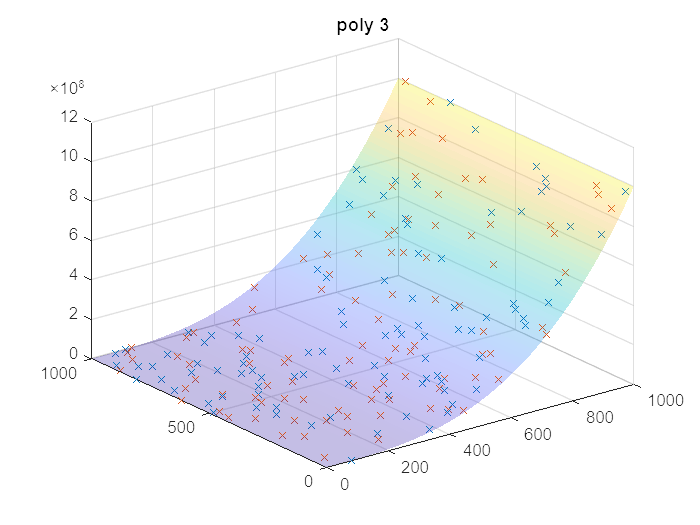

x = linspace(0,1000).';
y = linspace(0,1000).';
x = x (randperm(length(x)));
%y = y (randperm(length(x)));
z = x.^3+y.^2+3.*x+1;
[rmse_log_i,coeffs_i] = plot3_special(x,y,z,1,5);

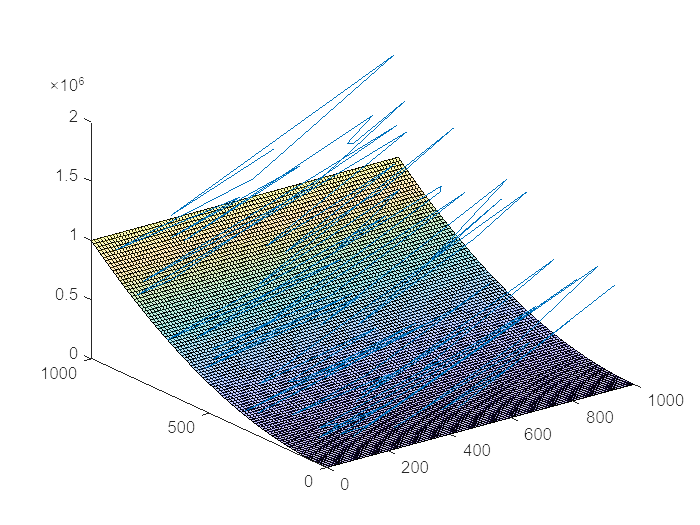

figure(100)
clf
plot3(x,y,z)
[X,Y]= meshgrid(x,y);
hold on
surf(X,Y,coeffs_i(1)*sin(deg2rad(X)).^2+coeffs_i(2).*Y.^2+coeffs_i(3),'FaceAlpha',0.3)